# **Project**

clear; close all; clc;
set(groot,'defaulttextinterpreter','Latex');
set(groot, 'defaultAxesTickLabelInterpreter','Latex');
set(groot, 'defaultLegendInterpreter','Latex');

## Preliminary

#### Constant Introduction

Var.lstar = 385692.5;                           % Characteristic length, km
Var.tstar = 377084.1526670386;                  % Characteristic time, s
Var.vstar = Var.lstar / Var.tstar;              % Characteristic velocity, km/s

Var.m1 = 398600.4328969393;                     % Gravitational parameter of Earth
Var.m2 = 4902.800582147765;                     % Gravitational parameter of Moon
Var.rEL = 384400;                               % Distance between Earth and Moon, nondim

Var.R1 = 6378;                                  % Radius of Earth, km
Var.R2 = 1737;                                  % Radius of Moon, km

Var.n = sqrt(Var.m1 / Var.rEL^3);               % Mean motion of Moon
Var.D1 = Var.m2 * Var.rEL / (Var.m1 + Var.m2);
Var.mu = Var.m2 / (Var.m1 + Var.m2);

Var.vecSize = 5000;                             % Attitude representation vector length, km

Var.L2x = L2LagrangePoint(Var.mu);              % L2 Lagrange Point (x)

Var.OrbFam = 1500;                              % Orbit Family # (the higher the more eccentric)

% S/C Parameter

%Var.J = diag([1,1,3/2]);                        % Moment of Inertia
%Var.K = JtoK(Var.J);

Var.J = rand(3);                                % Moment of Inertia

Var.m = 500 / (Var.m1 + Var.m2);                % Spacecraft mass (nondim)

Var.I = [Var.J zeros(3); zeros(3) Var.m*eye(3)];

#### Variable Introduction

Var.NumOrb = 1;                                 % Number of orbits to propagate

Var.tol = 1e-12;                                % Numerical Integration Tolerance
opt = odeset('Reltol', Var.tol,'Abstol', Var.tol);

Var.N = 32;                                     % MPC Window Step

#### MPC Setup

The cost function is $J=$

Q = 1000;
R = diag([1,1,1,10,10,10]);
mpciter = 0;

## Reference State History

Reference state is calculated from $x=\left\lbrack \begin{array}{cccccc}
x & y & z & \dot{x}  & \dot{y}  & \dot{z} 
\end{array}\right\rbrack$. Since it's just a reference, $\mathit{\mathbf{u}}=0\;\forall \;t$. 

% Southern Halo
load('Shaloorbits.mat');

init_ref = x_Halo2{1500}(1,1:6)';               % Initial Trajectory [x y z xdot ydot zdot]_0

X = ode45(@(t,X) StateSTMdot(t, X, Var.mu),[0 x_Halo2{1500}(end,end)], [init_ref; reshape(eye(6), [], 1)], opt);

Evaluate at $t$ with constant time-step, which easily discretizes. There are two options to define $t$: 1) define step-size, 2) define size of $t$ vector.

Since $N=32$, $30N$ points would be enough.

%t = 0:1e-3:x_Halo2{1500}(end,end)
t = linspace(0, x_Halo2{1500}(end,end), 10 * Var.N)';
T = t(2)-t(1);
X = deval(X, t);

pos_ref = X(1:3,:);                             % Reference position history
vel_ref = X(4:6,:);                             % Reference velocity history
STM_ref = reshape(X(7:end,:), 6,6,size(X,2));   % Reference STM history

For the attitude, have constant one for now:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Reference Attitude %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
att_ref = eye(3);                               % Reference (constant) attitude, DCM

%{
for i = 1:size(X,2)                             
    att_ref(:,:,i) = eye(3);                        
end                              
%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Reference Ang. Vel %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
omg_ref = zeros(3,size(X,2));                   % Reference angular velocity 
                                               

Convert to SE(3) state variable representation and repeat for Var.NumOrb:

g_ref = []; v_ref = [vel_ref; omg_ref];

for i = 1:size(X,2)
    g_ref(:,:,i) = SE3(att_ref, pos_ref(:,i));
end

Using cat: concatenate in 3D direction; start with initial condition but repeat from second index to end in order to avoid duplicate state at end which is the same as the first index of the succeeding matrix. Just in case, increase the number of orbits by one.

g_ref = cat(3, g_ref(:,:,1), repmat(g_ref(:,:,2:end), 1, 1, Var.NumOrb+1));
v_ref = [v_ref(:,1) repmat(v_ref(:,2:end), 1, Var.NumOrb+1)];

Now $g^0 \left(k\right)$ and $v^0 \left(k\right)$ are ready.

Check the plot of the reference trajectory

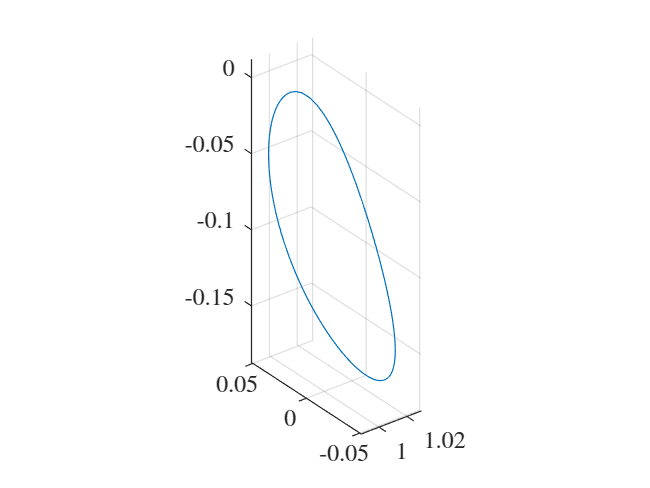

%
figure()
plot3(pos_ref(1,:), pos_ref(2,:), pos_ref(3,:)); grid
axis equal



figure()
plot3(squeeze(g_ref(1,4,:)),squeeze(g_ref(2,4,:)),squeeze(g_ref(3,4,:))); grid
axis equal

%}

## Spacecraft Initial Condition

C0 = att_ref;                                   % Initial C = [SB]
R0 = pos_ref(:,1);                              % Initial position
nu0 = vel_ref(:,1);                             % Initial velocity

w0 = omg_ref(:,1);                              % Initial angular velocity
%w0 = [pi pi/3 -0.05]';

g0 = SE3(C0, R0);
v0 = [w0; nu0];


## Nominal SE(3) Propagation

To verify the SE(3) dynamics and kinematics work, propagate the original SE(3) Equations of Motion

Out = SE3NumIntegrator(t, g0, v0, 0, Var.I, Var.mu); 

g_history = Out.g;
v_history = Out.v;

Analysis

for i = 1:length(t)
    [C, R] = invSE3(g_history(:,:,i));
    R_history(:,i) = R;
    C_history(:,:,i) = C;
end

Plotwork

figure()
hold; grid
PlotSys(Var)
plot3(Var.lstar*R_history(1,:), Var.lstar*R_history(2,:), Var.lstar*R_history(3,:))

axis equal

### Relative State 

May develop further into incorporating exp(SE(3)) error dynamics

%{
dC0 = att_ref' * C0;
dR0 = att_ref' * (R0 - pos_ref(:,1));

dg0_inv = SE3(C0' * att_ref, C0' * (pos_ref(:,1) - R0));

dg0 = SE3(dC0, dR0);
dv0 = v0 - Adj(dg0_inv) * vel_ref(:,1);
%}